% MATLAB Code for Binomial Model and Analysis
clc;
clear;

% Given parameters
S0 = 50; % Initial stock price
K = 52; % Strike price
T = 2; % Time to maturity in years
sigma = 0.3; % Volatility
r = 0.05; % Risk-free interest rate
steps = [12 * T, 52 * T, 252 * T]; % Number of steps for each setting

% Initialize variables for storing results
EuropeanPrices = zeros(1, length(steps));
AmericanPrices = zeros(1, length(steps));
BlackScholesPrice = BS(S0, K, r, 0, sigma, T, 'p');

% (a) Compute u, d, p for each setting
fprintf('Part (a): Compute u, d, p for each setting\n');

Part (a): Compute u, d, p for each setting


for i = 1:length(steps)
    dt = T / steps(i);
    u = exp(sigma * sqrt(dt));
    d = 1 / u;
    p = (exp(r * dt) - d) / (u - d);
    fprintf('For %d time steps (Delta t = %.4f): u = %.4f, d = %.4f, p = %.4f\n', steps(i), dt, u, d, p);
end

For 24 time steps (Delta t = 0.0833): u = 1.0905, d = 0.9170, p = 0.5024
For 104 time steps (Delta t = 0.0192): u = 1.0425, d = 0.9593, p = 0.5012
For 504 time steps (Delta t = 0.0040): u = 1.0191, d = 0.9813, p = 0.5005


% (b) Use binomial model for pricing European put options
fprintf('\nPart (b): European Put Option Prices\n');


Part (b): European Put Option Prices


for i = 1:length(steps)
    n = steps(i);
    dt = T / n;
    u = exp(sigma * sqrt(dt));
    d = 1 / u;
    p = (exp(r * dt) - d) / (u - d);

    % Initialize option values at maturity
    stockPrices = S0 * d.^(n:-1:0) .* u.^(0:n);
    optionValues = max(K - stockPrices, 0);

    % Backward induction
    for j = n:-1:1
        optionValues = exp(-r * dt) * (p * optionValues(2:end) + (1 - p) * optionValues(1:end-1));
    end
    EuropeanPrices(i) = optionValues(1);
    fprintf('European Put Option Price with %d steps: %.4f\n', n, optionValues(1));
end

European Put Option Price with 24 steps: 6.7874
European Put Option Price with 104 steps: 6.7775
European Put Option Price with 504 steps: 6.7570


fprintf('Black-Scholes Put Option Price: %.4f\n', BlackScholesPrice);

Black-Scholes Put Option Price: 6.7601


% (c) Plot results for varying time steps
fprintf('\nPart (c): Plot Results for Varying Time Steps\n');


Part (c): Plot Results for Varying Time Steps


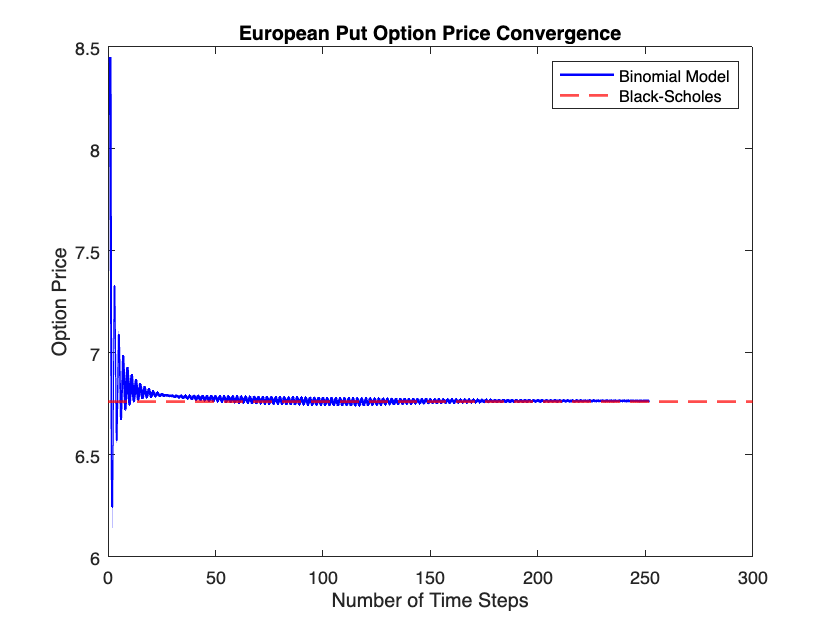

timeSteps = 1:252;
prices = zeros(1, length(timeSteps));
for n = timeSteps
    dt = T / n;
    u = exp(sigma * sqrt(dt));
    d = 1 / u;
    p = (exp(r * dt) - d) / (u - d);

    stockPrices = S0 * d.^(n:-1:0) .* u.^(0:n);
    optionValues = max(K - stockPrices, 0);

    for j = n:-1:1
        optionValues = exp(-r * dt) * (p * optionValues(2:end) + (1 - p) * optionValues(1:end-1));
    end
    prices(n) = optionValues(1);
end

figure;
plot(timeSteps, prices, 'b', 'LineWidth', 1.5);
hold on;
yline(BlackScholesPrice, 'r--', 'LineWidth', 1.5);
xlabel('Number of Time Steps');
ylabel('Option Price');
title('European Put Option Price Convergence');
legend('Binomial Model', 'Black-Scholes');

% (d) Terminal stock price distribution for selected steps
fprintf('\nPart (d): Terminal Stock Price Distributions\n');


Part (d): Terminal Stock Price Distributions


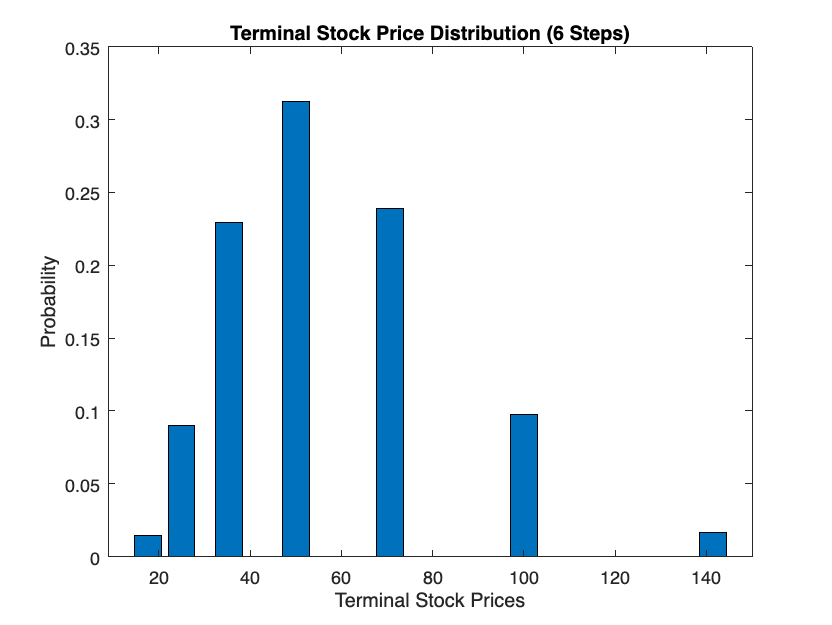

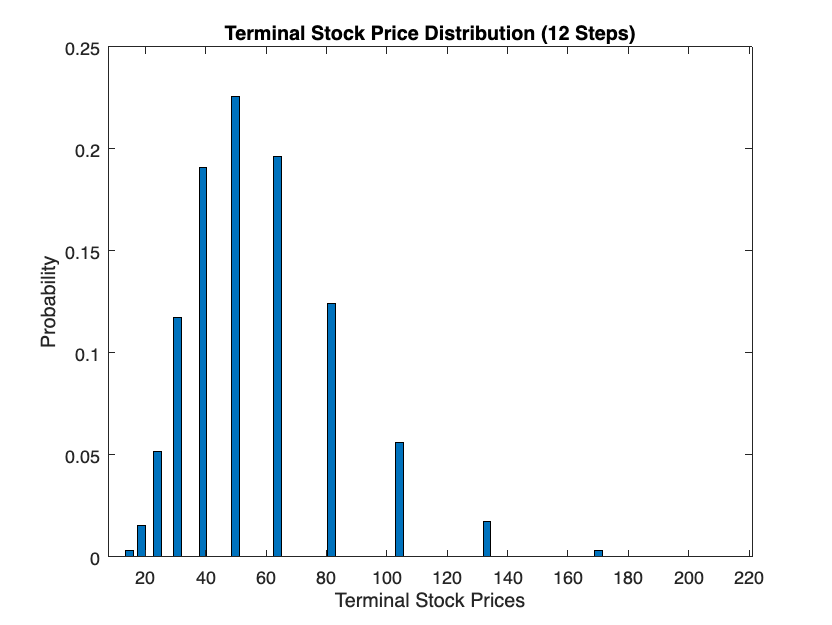

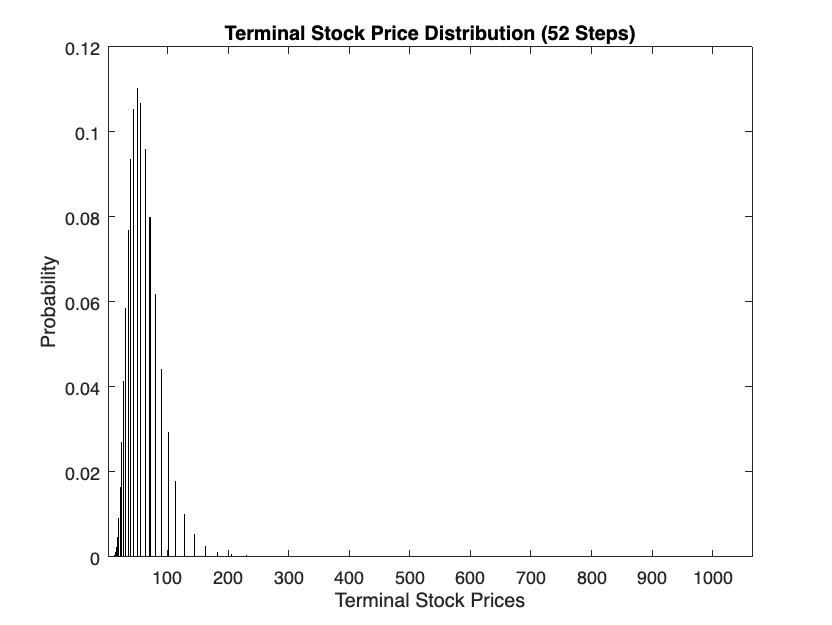

timeStepsForDist = [6, 12, 52];
for n = timeStepsForDist
    dt = T / n;
    u = exp(sigma * sqrt(dt));
    d = 1 / u;
    p = (exp(r * dt) - d) / (u - d);

    stockPrices = S0 * d.^(n:-1:0) .* u.^(0:n);
    probabilities = binopdf(0:n, n, p);

    figure;
    bar(stockPrices, probabilities);
    xlabel('Terminal Stock Prices');
    ylabel('Probability');
    title(sprintf('Terminal Stock Price Distribution (%d Steps)', n));
end

% (e) Modify to compute American put option values
fprintf('\nPart (e): American Put Option Prices\n');


Part (e): American Put Option Prices


for i = 1:length(steps)
    n = steps(i);
    dt = T / n;
    u = exp(sigma * sqrt(dt));
    d = 1 / u;
    p = (exp(r * dt) - d) / (u - d);

    stockPrices = S0 * d.^(n:-1:0) .* u.^(0:n);
    optionValues = max(K - stockPrices, 0);

    for j = n:-1:1
        stockPrices = stockPrices(1:end-1) / d;
        optionValues = max(exp(-r * dt) * (p * optionValues(2:end) + (1 - p) * optionValues(1:end-1)), K - stockPrices);
    end
    AmericanPrices(i) = optionValues(1);
    fprintf('American Put Option Price with %d steps: %.4f\n', n, optionValues(1));
end

American Put Option Price with 24 steps: 7.5075
American Put Option Price with 104 steps: 7.4856
American Put Option Price with 504 steps: 7.4710
